**EXPLORING THE DATA**

**What does the data look like? **

- **How did the authors structure their data?**

- **What are the physical dimensions, the size, and the frame rate of data? **

- **How is the behavior coded? **

% written by Christian Pritz 2025 | Computation Neuroscience course 
% | Department of Neuroscience | UniTo | 

load('WT_NoStim.mat');
disp(WT_NoStim)

  1×5 struct array with fields:

    deltaFOverF
    deltaFOverF_bc
    Opts
    NeuronNames
    tv
    dataset
    fps
    States
    derivs
    stateParams



disp(['There are ', num2str(numel(WT_NoStim)), ' animals stored in this structured array.'])

There are 5 animals stored in this structured array.



WT_NoStim(1).deltaFOverF_bc

ans =     0.1971    0.2773    0.1541    0.1572    0.2030    0.1381    0.0720    0.1944    0.0963    0.1078    0.1824    0.1907    0.4280    0.2458    0.5397    0.5171    0.1817    0.2200    0.2241    0.0649    0.0700    0.1895    0.2163    0.5240    0.1419    0.1812    0.0591    0.1123    0.4401    0.4318    0.1756    0.3534    0.0730    0.0399    0.1390    0.0437    0.0708    0.1842    0.2882    0.2348    0.1043    0.2584    0.5584    0.1614    0.4371    0.0682    0.0809    0.0845    0.1006    0.1340
    0.1932    0.2798    0.1616    0.1330    0.1898    0.0843    0.0685    0.2171    0.0941    0.1294    0.1626    0.1998    0.4097    0.2504    0.5140    0.5731    0.1538    0.2463    0.2256    0.0528    0.1151    0.2587    0.2573    0.5281    0.1217    0.1369    0.0111    0.1306    0.4633    0.4616    0.1189    0.3155    0.0774    0.0520    0.1301    0.0598    0.0600    0.1500    0.2999    0.2472    0.0672    0.2367    0.5352    0.2201    0.4358    0.0499    0.0864    0.0609    0.0924   

figure(),imagesc(WT_NoStim(1).deltaFOverF_bc')
figure(),imagesc(WT_NoStim(2).deltaFOverF_bc')

%THIS 5 animals have different numbers of neurons and different recording
%lengths and framerates

for i=1:5
    disp(['Animal number ', num2str(i), ' has ', num2str(size(WT_NoStim(i).deltaFOverF_bc,1)),' frames, ',num2str(size(WT_NoStim(i).deltaFOverF_bc,2)),' neurons, and a ',num2str(WT_NoStim(i).fps), ' Hz frame rate.'])
end

Animal number 1 has 3137 frames, 109 neurons, and a 2.9046 Hz frame rate.
Animal number 2 has 3134 frames, 135 neurons, and a 2.9019 Hz frame rate.
Animal number 3 has 3059 frames, 131 neurons, and a 2.8324 Hz frame rate.
Animal number 4 has 3311 frames, 125 neurons, and a 3.0657 Hz frame rate.
Animal number 5 has 3021 frames, 129 neurons, and a 2.7972 Hz frame rate.



%This means timepoint 10 in animal one is not equal 
% to equal to time point 10 in animal 2. We cannot 
% simply pool the data for our analysis. 


% to make our live easier here is an extraction function...
% this fetches neural activities, time vector, behavioral states, and a state_vector
% It also interpolates all the activities to same frame rate. 

sttngs.frameRate = 3; %FPS
sttngs.interval = 1:3000; %this is measured in datapoints 
sttngs.kernelSize = 20; % this is for later smoothing of the latent variables
sttngs.commonNrns = getCommonNeurons(WT_NoStim); %extracting common neurons from all the animals

###########################################################
     2

--------------------------------------------------------
   109

   109

   135

###########################################################
     3

--------------------------------------------------------
    83

    83

   131

###########################################################
     4

--------------------------------------------------------
    66

    66

   125

stop
###########################################################
     5

--------------------------------------------------------
    51

    51

   129



sttngs.cleanUpNrns = true; %if this is set true, only common neurons will be used

sttngs.property = 'deltaFOverF_bc' %'derivs.traces' or 'deltaFOverF_bc'

sttngs = struct with fields:
      frameRate: 3
       interval: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 … ] (1×3000 double)
     kernelSize: 20
       property: 'deltaFOverF_bc'
     commonNrns: {'AIBL'  'AIBR'  'ALA'  'ASKR'  'AVAL'  'AVAR'  'AVBL'  'AVBR'  'AVEL'  'AVER'  'RIBL'  'RID'  'RIML'  'RIMR'  'RIVL'  'RIVR'  'RMED'  'RMEL'  'RMER'  'SMDDR'  'SMDVR'  'VB02'}
    cleanUpNrns: 1


%fetching the data from the structured cell
animal_num = 3

animal_num = 3

[data,time,states,state_vector,nrns] = getData(WT_NoStim,animal_num,sttngs); % fetching and interpolating

CONSISTENCY: data size 1 Nrns 1


visualizeActivities_2(data,nrns,sttngs.frameRate,36)





%The dataset also includes the first derivative of the neural activities
animal_num = 1

animal_num = 1

sttngs.property = 'derivs.traces' %'derivs.traces' or 'deltaFOverF_bc'

sttngs = struct with fields:
      frameRate: 3
       interval: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 … ] (1×3000 double)
     kernelSize: 20
       property: 'derivs.traces'
     commonNrns: {'AIBL'  'AIBR'  'ALA'  'ASKR'  'AVAL'  'AVAR'  'AVBL'  'AVBR'  'AVEL'  'AVER'  'RIBL'  'RID'  'RIML'  'RIMR'  'RIVL'  'RIVR'  'RMED'  'RMEL'  'RMER'  'SMDDR'  'SMDVR'  'VB02'}
    cleanUpNrns: 1


[data,time,states,state_vector,nrns] = getData(WT_NoStim,animal_num,sttngs); % fetching and interpolating

CONSISTENCY: data size 1 Nrns 1


visualizeActivities_2(data,nrns,sttngs.frameRate,36)

%it allow provides us with a behavioral annotation. 
figure(),plot(time,state_vector);
xlabel('Time (s)')
ylabel('behavioral states');

fields = fieldnames(WT_NoStim(1).States);
for i=1:numel(fields)
    disp([num2str(i),' is ', fields{i}])
end

1 is fwd
2 is slow
3 is dt
4 is vt
5 is rev1
6 is rev2
7 is revsus
8 is nostate


**Let us do a PCR on a single animal **

- **getting the data**

- **normalizing the data**

- **running the PCR **

- **plotting the results **

close all

sttngs.frameRate = 3; % frames per second
sttngs.interval = 1:3000; %this is measured in datapoints 
sttngs.kernelSize = 20; % this is for later smoothing of the latent variables
sttngs.commonNrns = getCommonNeurons(WT_NoStim); %extracting common neurons from all the animals

###########################################################
     2

--------------------------------------------------------
   109

   109

   135

###########################################################
     3

--------------------------------------------------------
    83

    83

   131

###########################################################
     4

--------------------------------------------------------
    66

    66

   125

stop
###########################################################
     5

--------------------------------------------------------
    51

    51

   129



sttngs.cleanUpNrns = true; %if this is set true, only common neurons will be used
sttngs.property = 'derivs.traces' %'derivs.traces' or 'deltaFOverF_bc'

sttngs = struct with fields:
      frameRate: 3
       interval: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 … ] (1×3000 double)
     kernelSize: 20
       property: 'derivs.traces'
     commonNrns: {'AIBL'  'AIBR'  'ALA'  'ASKR'  'AVAL'  'AVAR'  'AVBL'  'AVBR'  'AVEL'  'AVER'  'RIBL'  'RID'  'RIML'  'RIMR'  'RIVL'  'RIVR'  'RMED'  'RMEL'  'RMER'  'SMDDR'  'SMDVR'  'VB02'}
    cleanUpNrns: 1



animal_num = 2

animal_num = 2


[data,time,states,state_vector,nrns] = getData(WT_NoStim,animal_num,sttngs); % fetching and interpolating

CONSISTENCY: data size 1 Nrns 1




if sttngs.cleanUpNrns
    [yn,loc]=ismember(sttngs.commonNrns,nrns);
    data = data(loc,:);
    nrns = sttngs.commonNrns;
end

nrns = 1×22 cell array
    {'AIBL'}    {'AIBR'}    {'ALA'}    {'ASKR'}    {'AVAL'}    {'AVAR'}    {'AVBL'}    {'AVBR'}    {'AVEL'}    {'AVER'}    {'RIBL'}    {'RID'}    {'RIML'}    {'RIMR'}    {'RIVL'}    {'RIVR'}    {'RMED'}    {'RMEL'}    {'RMER'}    {'SMDDR'}    {'SMDVR'}    {'VB02'}


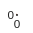

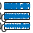

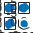

     1

    0.1207

     2



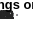

   -0.0492

     3



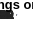

    0.0804



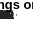

smoothTrajectory is not found in the current folder or on the MATLAB path, but exists in:
    /home/christian/Documents/teaching activities/Manifolds/computational part/code/old

Change the MATLAB current folder or add its folder to the MATLAB path.


% normalizing the data

data = zscore(data, 0, 1);  

[coeff, score, ~,~, explained] = pca(data', 'NumComponents', 10);

latent = score';
plot_variance_explained(explained,20)
plot_pcs(latent,sttngs)
plot_coeffs(coeff,3,nrns)

%visualize latent activity over time: 
[s_latent] = smoothTrajectory(latent,7)
visualize_time(s_latent,state_vector,states,100);



**Let's add some noise to the data and see how it affects the manifold **

close all 

sttngs.frameRate = 3; % frames per second
sttngs.interval = 1:3000; %this is measured in datapoints 
sttngs.kernelSize = 20; % this is for later smoothing of the latent variables
sttngs.commonNrns = getCommonNeurons(WT_NoStim); %extracting common neurons from all the animals
sttngs.cleanUpNrns = true; %if this is set true, only common neurons will be used
sttngs.property = 'deltaFOverF_bc' %'derivs.traces' or 'deltaFOverF_bc'

animal_num = 2

[data,time,states,state_vector,nrns] = getData(WT_NoStim,animal_num,sttngs); % fetching and interpolating


if sttngs.cleanUpNrns

    [yn,loc]=ismember(sttngs.commonNrns,nrns);
    data = data(loc,:);
    nrns = sttngs.commonNrns;
end

amplitude = max(data,[],"all")-min(data,[],"all")
noise = randn(size(data))*amplitude*0.01;
data= data + noise;

% normalizing the data
data = zscore(data, 0, 1);  

[coeff, score, ~,~, explained] = pca(data', 'NumComponents', 10);

latent = score';
plot_variance_explained(explained,20)
plot_pcs(latent,sttngs)
plot_coeffs(coeff,3,nrns)

%visualize latent activity over time: 
[s_latent] = smoothTrajectory(latent,7)
visualize_time(s_latent,state_vector,states,100);


**Run the an ISOMAP estimation of the latent activity on a single animal**

close all 

sttngs.frameRate = 3; % frames per second
sttngs.interval = 1:3000; %this is measured in datapoints 
sttngs.kernelSize = 20; % this is for later smoothing of the latent variables
sttngs.commonNrns = getCommonNeurons(WT_NoStim); %extracting common neurons from all the animals
sttngs.cleanUpNrns = true; %if this is set true, only common neurons will be used
sttngs.property = 'deltaFOverF_bc' %'derivs.traces' or 'deltaFOverF_bc'

animal_num = 2

[data,time,states,state_vector,nrns] = getData(WT_NoStim,animal_num,sttngs); % fetching and interpolating


if sttngs.cleanUpNrns

    [yn,loc]=ismember(sttngs.commonNrns,nrns);
    data = data(loc,:);
    %visualizeActivities_2(data,sttngs.commonNrns,sttngs.frameRate);
    nrns = sttngs.commonNrns
end

% normalizing the data
data = zscore(data, 0, 1);  

latent = neural_ISOMAP(data', 8, 3);
[s_latent] = smoothTrajectory(latent',7)'

figure(),
visualize_time(s_latent,state_vector,states,100);



**Comapring different animals**

- **Projecting the latent values of several animals  into a common space**

close all 

sttngs.frameRate = 3;
sttngs.interval = 1:1000;
sttngs.kernelSize = 20; % this is for later smoothing of the latent variables
sttngs.property = 'derivs.traces'
sttngs.commonNrns = getCommonNeurons(WT_NoStim); %extracts neurons common to all 
sttngs.cleanUpNrns = false;


%This performs PCA on all animals
[latent,coeffs,states,states_vec] = per_animal_PCA(WT_NoStim,sttngs)
%This aligns the latent activities with each other
[alignedData] = align_trajectories(latent,states_vec)


figure(),
ndims=1:500
hold on 
for i=1:3
    plot3(latent{i}(1,ndims),latent{i}(2,ndims),latent{i}(3,ndims),'.-')
end

hold off
axis equal



figure(),
hold on 
goodGuys = [1,2,4]
for i=1:numel(goodGuys)
    plot3(alignedData{goodGuys(i)}(1,:),alignedData{goodGuys(i)}(2,:),alignedData{goodGuys(i)}(3,:),'.-')
end

hold off
axis equal


pooledPC = []
pooledVec = [];
goodGuys = [1,2]
for i=1:numel(goodGuys)
    pooledPC = horzcat(pooledPC,alignedData{goodGuys(i)});
    pooledVec = horzcat(pooledVec,states_vec{goodGuys(i)});
end

plot_trajectories(pooledPC,pooledVec,states{i})




**Let us do multiple animals. **

- **perform per-animal PCR**

- **register the data**

**Registering the data on behavior**

sttngs.frameRate = 3;
sttngs.interval = 1:3000;
sttngs.kernelSize = 20; % this is for later smoothing of the latent variables
sttngs.property = 'derivs.traces'
sttngs.cleanUpNrns = true;
sttngs.commonNrns = getCommonNeurons(WT_NoStim); %extracts neurons common to all 

[latent,coeffs,states,states_vec] = per_animal_PCA(WT_NoStim,sttngs)

seq = []
Ps = []
followUps = []

for i=1:numel(states_vec)
    disp(i)
    
    seq_i = squashRepeats(states_vec{i});
    seq = horzcat(seq,seq_i);
    [p,a] = transitionMatrix(seq_i); 
    Ps(:,:,i) = p(1:7,1:7);
    followUps(:,i) = a(1:7);

end
 
[P,followUps,props] = transitionMatrix(seq);
figure(),imagesc(P)
[regist_latents,regist_states,state_stats] = register_states2(states_vec,latent,1:7,2)
plot_trajectories(regist_latents{1},regist_states{1},states{1})

%
aligned_latents = align_latents_cancorr(regist_latents, 1)




pooled_latents  = [];
pooled_states = [];
for i=[1,2,3]
    pooled_latents = [pooled_latents,aligned_latents{i}];
    pooled_states = [pooled_states,regist_states{i}];
end
plot_trajectories(pooled_latents,pooled_states,states{1})

killDx = isnan(pooled_latents);
killDx=find(killDx(1,:)==1);
clean_latent = pooled_latents;
clean_states =  pooled_states;
clean_latent(:,killDx) = [];
clean_states(killDx(1,:)) = [];

%what about the dimensionality of the manifold? 

[coeff, score, ~,~, explained] = pca(clean_latent', 'NumComponents', 3);
plot_variance_explained(explained,4)
